# TDE 21 OTTOBRE 2022

## Q2

clear;
clc;

L1 = 2; % [m]
L2 = 1; % [m]
% bang-bang profile
Vmax_1 = 2; % [rad/s] limit on q_dot_1
Vmax_2 = 1.5; % [rad/s] limit on q_dot_2
p_i = [2+1/sqrt(2); 1/sqrt(2)];
p_f = [3/sqrt(2); -1/sqrt(2)];
p_dot_i = 0;
p_dot_f = 0;
% T to be minimized
% t_i t_f same for both joints
% no singularity crossing
% T_min? 
% |A_max|?(1,2)
% plot profiles for q_dbdot_1, q_dbdot_2 in t bel [0,T]

% need of conversion on joint space being the boundaries in
% joint space
syms l1 l2 q1 q2 real
robot = robot_planar_2R()

robot =   robot_planar_2R with properties:

         l1: l1
         l2: l2
         q1: q1
         q2: q2
          p: [3×1 sym]
    dhtable: [2×4 sym]
          T: [4×4 sym]
       A0_1: [4×4 sym]
       A1_2: [4×4 sym]


p = robot.p;
% p =[l2*cos(q1 + q2) + l1*cos(q1); l2*sin(q1 + q2) + l1*sin(q1); sym(0)]
% p_dot = diff(p, t)
% choice of both "+" signs in order to avoid singularity crossing
[q1_i, q2_i] = inverse(robot, L1, L2, p_i, 'pos');
q_i = [q1_i; q2_i].*(180/pi)

q_i =    -0.0000
   45.0000


[q1_f, q2_f] = inverse(robot, L1, L2, p_f, 'pos');
q_f = [q1_f; q2_f] .*(180/pi)

q_f =   -45.0000
   90.0000


Dq = q_f - q_i

Dq =   -45.0000
   45.0000


A_max_1 = (Vmax_1^2)/deg2rad(Dq(1));
A_max_2 = (Vmax_2^2)/deg2rad(Dq(2));
T1 = sqrt(4*deg2rad(Dq(1))/A_max_1);

T1 = 0.7854

T2 = sqrt(4*deg2rad(Dq(2))/A_max_2);

T2 = 1.0472

T = T2
Vmax_1 = 2*deg2rad(Dq(1))/T;

Vmax_1 = -1.5000

A_max_1 = Vmax_1^2/deg2rad(Dq(1));

A_max_1 = -2.8648

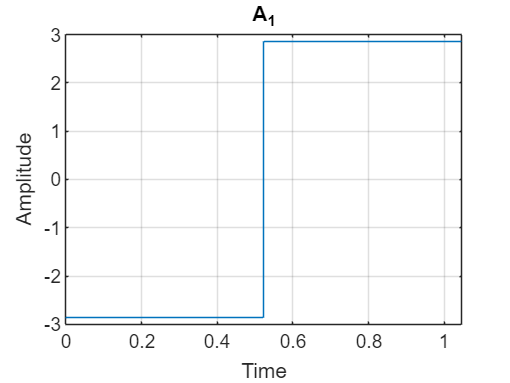

% plot 1
DT = [0, T/2, T];
A = [A_max_1, -A_max_1, -A_max_1];

% Plot the step function
stairs(DT, A);

% Add labels and title
grid on
xlabel('Time');
ylabel('Amplitude');
title('A_1');

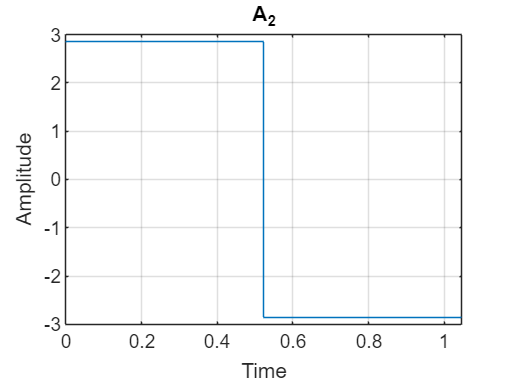


% plot 2
DT = [0, T/2, T];
A = [A_max_2, -A_max_2, -A_max_2];

% Plot the step function
stairs(DT, A);

% Add labels and title
grid on
xlabel('Time');
ylabel('Amplitude');
title('A_2');


% note that we could have choose the positive sign, but 
% we would have encounter